# Sprawozdanie Interpolacja

Tomasz Kowalski 313565

*---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------*

clc
clear
close all

#### Dane wejściowe do interpolacji Wielomanem Lagranage'a i Newtona

**Funkcja do interpolacji:    **$f\left(x\right)=\frac{1}{1+x^{10} }$** w przedziale **$<-1\;;1>$** dla 7 punktów interpolacyjnych równo rozłożonych.**

xd = -1;    %dolny zakres funkcji
xu = 1;     %górny zakres funkcji
len = 7;   %ilość punktów interpolacji

xi = linspace (xd,xu,1000);     %x do wykresu
yi = 1./(1+(xi.^10));           %y do wykresu


x = linspace(xd,xu,len);    %x punktów do interpolacji
y = 1./(1+x.^10);           %y punktów do interpolacji


*---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------*

### Algorytm interpolacji wielomanem Lagrange'a    (Zad 1)

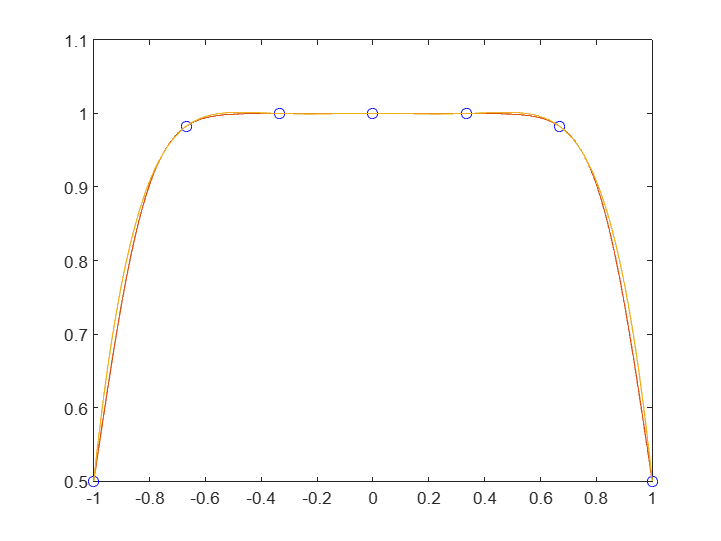

%ALGORYTM
pl = zeros(1,len);           %wielomian interpolacyjny Lagrange'a

for i = 1 : len
    tmp1 = x;
    tmp1(i) = [];
    tmp2 = poly(tmp1);
    tmp1 = x(i) - tmp1;
    tmp2 = tmp2 * y(i) / prod(tmp1);
    pl = pl + tmp2;
end

%obliczenie punktów do wykresu funkcji interpolacyjnej
yo=polyval(pl,xi);

figure;
plot(x,y,'ob'); hold on;
plot(xi,yi);
plot(xi,yo);

*---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------*

### Algorytm interpolacji wielomianem Newtona    (Zad 2)

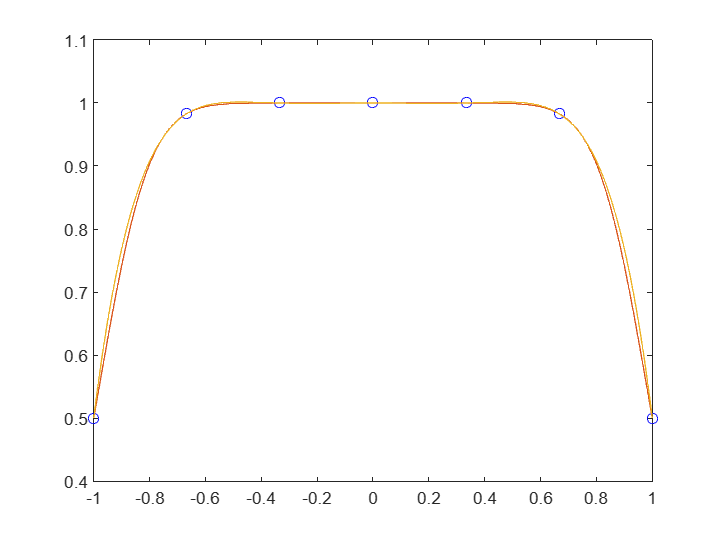

pn = zeros(1,len);      %wielomian interpolacyjny Newtona
f = zeros(len,len);

%ALGORYTM
f(:,1) = y;
for j = 2 : len
    for i = j : len
        f(i,j) = (f(i,j-1)-f(i-1,j-1))/(x(i)-x(i-j+1));
    end
end

pn(1) = y(1);

for j = 2 : len
    tmp = zeros(1,j-1);
    for a = 1 : j-1
        tmp(a)=x(a);
    end
    tmp = poly(tmp);
    tmp = flip(tmp);
    tmp = tmp * f(j,j);
    for a = 1 : j
        pn(a) = pn(a) + tmp(a);
    end

end

pn = flip(pn);

%obliczenie punktów do wykresu funkcji interpolacyjnej
yo=polyval(pn,xi);

figure;
plot(x,y,'ob'); hold on;
plot(xi,yi);
plot(xi,yo);

#### Porównanie współczynników wielomianu Lagrange'a i Newtona

p = zeros(2,len);
p(1,:) = pl;
p(2,:) = pn;
format shortG
disp(p);

     -0.80591  -1.9984e-15      0.33312   1.8319e-15    -0.027217  -1.3566e-15            1
     -0.80591   1.1102e-16      0.33312   2.2204e-16    -0.027217  -4.1633e-17            1



**Możemy zauważyć że oba algorytmy dają wielomaian interpolacyjny o bardzo podobnych współczynnikach. Możemy z tego wywnioskować że obie metody są równoważne.**

*---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------*

### Eksperyment numeryczny wpływ ilości węzłów interpolacyjnych na dokładność interpolacji (Zad 4)

#### Węzły interpolacyjne równoodległe od siebie.

**Wybrałem 3 równe funkcje do interpolacji:**

**a)    **$a\left(x\right)=\sin \left(x\right)$** dla **$x\in <-3\;;\;2$**>    od 6 do 30 węzłów interpolacyjnych**

**b)    **$b\left(x\right)=e^{\sin \left(x\right)}$** dla **$x\in <0\;;10$**>    od 6 do 25 węzłów intepolacyjnych **

**c)    **$c\left(x\right)=\ln \left(x\right)*\sin \left(x\right)$**   dla **$x\in <1,5\;;\;21,5$**>    od 6 do 25 węzłów interpolacyjnych**

**dla każdego przypadku obliczam sredni oraz maksymalny błąd bezwzględny oraz względny. dla odpowiednio od 2 : 50 węzłów interpolacyjnych. Interpolację będziemy wykonywać wielomianem Lagrange'a aby pokazać Rungego.**

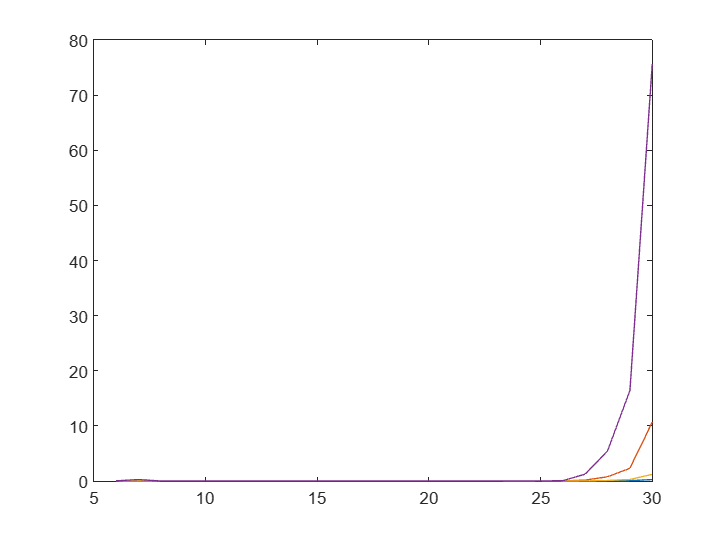

% a)

xd = -3;
xu = 2;
wb = zeros(1,24);
eb4a = zeros(4,24);

for len = 6 : 30
    %len = 2;
    
    
    
    xi = linspace (xd,xu,1000);
    yi = sin(xi);
    
    
    x = linspace(xd,xu,len);
    y = sin(x);
    p = zeros(1,len);
    
    for i = 1 : len
        tmp1=x;
        tmp1(i) = [];
        tmp2=poly(tmp1);
        tmp1=x(i)-tmp1;
        tmp2=tmp2*y(i)/prod(tmp1);
        p=p+tmp2;
    end
    
    b = zeros(2,1000);
    yo=polyval(p,xi);
    
    
    for a = 1 : 1000
        b(1,a) = abs(yi(a)-yo(a));
        b(2,a) = b(1,a)/abs(yi(a));
    end

    eb4a(1,len-5) = mean(b(1,:));
    eb4a(2,len-5) = max(b(1,:));
    eb4a(3,len-5) = mean(b(2,:));
    eb4a(4,len-5) = max(b(2,:));

    wb(len-5) = len;

end


figure;
plot(wb,eb4a);

format shortG
disp([wb;eb4a]);

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25           26           27           28           29           30
    0.0031315     0.001071   9.9075e-05    2.822e-05   2.2248e-06    5.485e-07   3.7831e-08   8.2304e-09   4.6842e-10   1.6222e-10   3.1754e-10   2.9638e-12   1.0136e-08   9.9108e-09   2.6471e-07   2.7874e-09   9.9433e-07   4.1153e-05   0.00016982    3.601e-05   0.00038566    0.0048202     0.025695     0.063623      0.26939
     0.014093    0.0043887   0.00063864   0.00016759   1.9314e-05   4.3803e-06   4.1603e-07   8.3116e-08   5.8803e-09   1.9415e-09   5.3645e-09   5.7572e-11   1.9482e-07   1.6382e-07   6.2761e-06   6.6961e-08   2.8829e-05    0.0011013    0.0048651    0.0015217    0.0094247       0.1766      0.77271       2.3179       10.683
    0.0062054    0.002

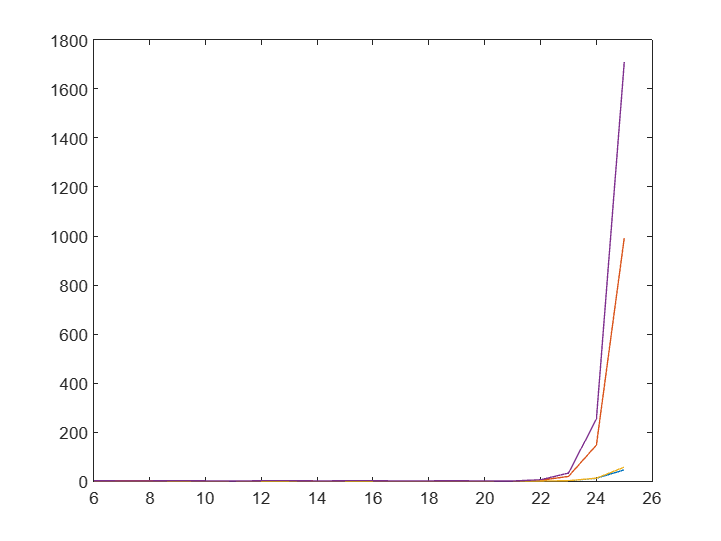

% b)

xd = 0;
xu = 10;
wb = zeros(1,19);
eb4b = zeros(4,19);

for len = 6 : 25
    %len = 2;
    
    
    
    xi = linspace (xd,xu,1000);
    yi = exp(sin(xi));
    
    
    x = linspace(xd,xu,len);
    y = exp(sin(x));
    p = zeros(1,len);
    
    for i = 1 : len
        tmp1=x;
        tmp1(i) = [];
        tmp2=poly(tmp1);
        tmp1=x(i)-tmp1;
        tmp2=tmp2*y(i)/prod(tmp1);
        p=p+tmp2;
    end
    
    b = zeros(2,1000);
    yo=polyval(p,xi);
    
    
    for a = 1 : 1000
        b(1,a) = abs(yi(a)-yo(a));
        b(2,a) = b(1,a)/abs(yi(a));
    end

    eb4b(1,len-5) = mean(b(1,:));
    eb4b(2,len-5) = max(b(1,:));
    eb4b(3,len-5) = mean(b(2,:));
    eb4b(4,len-5) = max(b(2,:));

    wb(len-5) = len;

end


figure;
plot(wb,eb4b);

format shortG
disp([wb;eb4b]);

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25
      0.28903      0.27087      0.20811       0.1643      0.11632      0.03922      0.10083     0.079279     0.045796     0.035487     0.042575     0.019374     0.042296     0.029108     0.017026    0.0092805      0.17314       1.2467       11.203       45.574
       1.1912      0.95146       1.1298       1.4644      0.71281      0.36956      0.85592        1.169      0.82763      0.71516      0.77353      0.44346      0.69667       0.7868      0.29339      0.12918       3.0081       18.886       146.81       994.51
      0.24188      0.20042      0.16337      0.15202     0.095499     0.028682     0.093642     0.087414     0.033687     0.043135     0.049203     0.024317      0.04354     0.037985     0.019301    0.0090845      0.1

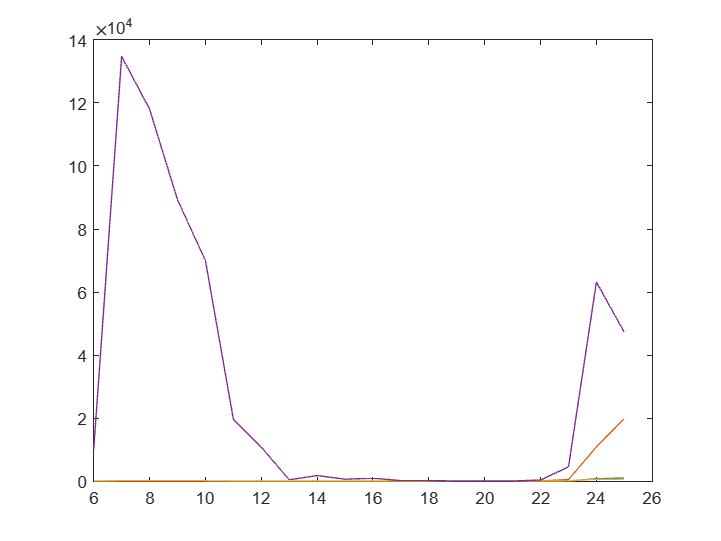

% c)

xd = 1.5;
xu = 21.5;
wb = zeros(1,19);
eb4c = zeros(4,19);

for len = 6 : 25    
    
    xi = linspace (xd,xu,1000);
    yi = log(xi).*sin(xi);
    
    
    x = linspace(xd,xu,len);
    y = log(x).*sin(x);
    p = zeros(1,len);
    
    for i = 1 : len
        tmp1=x;
        tmp1(i) = [];
        tmp2=poly(tmp1);
        tmp1=x(i)-tmp1;
        tmp2=tmp2*y(i)/prod(tmp1);
        p=p+tmp2;
    end
    
    b = zeros(2,1000);
    yo=polyval(p,xi);
    
    
    for a = 1 : 1000
        b(1,a) = abs(yi(a)-yo(a));
        b(2,a) = b(1,a)/abs(yi(a));
    end

    eb4c(1,len-5) = mean(b(1,:));
    eb4c(2,len-5) = max(b(1,:));
    eb4c(3,len-5) = mean(b(2,:));
    eb4c(4,len-5) = max(b(2,:));

    wb(len-5) = len;

end


figure;
plot(wb,eb4c);


format shortG
disp([wb;eb4c]);

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25
       1.9446        2.966        1.677       2.2913       1.3147       1.0005      0.60849      0.29496      0.18606      0.06373     0.041237     0.010722    0.0077089    0.0014147    0.0073748     0.036708       2.8622       39.448       717.31       948.44
       6.9629       10.758       8.2258       14.869       9.8519       9.2637       5.8149       3.5587        2.166      0.95474      0.56613      0.19369      0.11121     0.027391      0.13978      0.23832       32.962       446.06        10833        19910
       13.306       141.78       123.21        92.97       73.026       21.036       11.824      0.71456       2.0005      0.64555      0.95057      0.13409      0.16315     0.014673     0.019977      0.05109       2.

**Na każdym z wykresów możemy zauważyć że w pewnym momęcie błędy zaczynają gwałtownie rosnąć. Jesto to spowodowane efektem Rungego.**

(Efekt Rungego – pogorszenie jakości interpolacji wielomianowej, mimo zwiększenia liczby jej węzłów. Początkowo ze wzrostem liczby węzłów *n* przybliżenie poprawia się, jednak po dalszym wzroście *n,* zaczyna się pogarszać, co jest szczególnie widoczne na końcach przedziałów.

Takie zachowanie się wielomianu interpolującego jest zjawiskiem typowym dla interpolacji za pomocą wielomianów wysokich stopni przy stałych odległościach węzłów. Występuje ono również, jeśli interpolowana funkcja jest nieciągła albo odbiega znacząco od funkcji gładkiej. *źródło Wikipedia)*

*---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------*

### Eksperyment numeryczny wpływ ilości węzłów interpolacyjnych na dokładność interpolacji (Zad 5)

#### Węzły interpolacyjne rozłożone zgodnie z zasadą Czybyszewa.

**Fuknkcje przedziały i ilość węzłów jest taka sama jak w poprzednim zadaniu.**

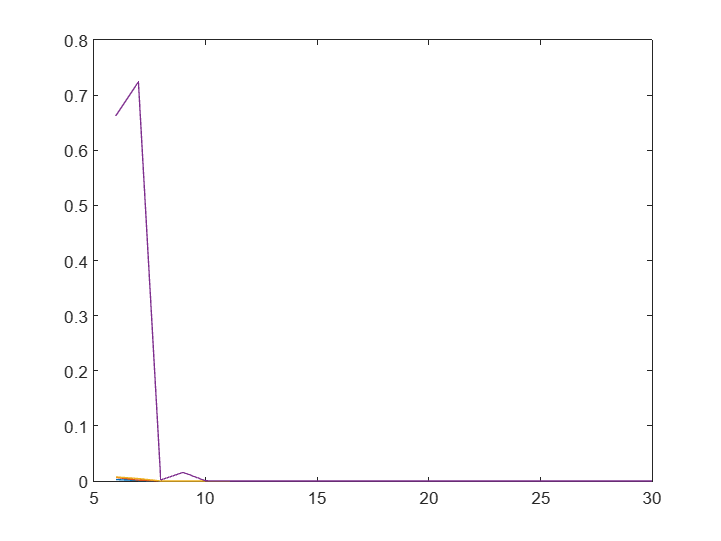

% a)

xd = -3;
xu = 2;
wb = zeros(1,24);
eb5a = zeros(4,24);

for len = 6 : 30
    %len = 2;
    
    
    
    xi = linspace (xd,xu,1000);
    yi = sin(xi);
    
    
    x = zeros(1,len);
    for c = 1 : len
        x(c) = cos((2*c-1)*pi/(2*len));
    end
    
    x = (x+1)*(xu-xd)/2+xd;
    y = sin(x);
    p = zeros(1,len);
    
    for i = 1 : len
        tmp1=x;
        tmp1(i) = [];
        tmp2=poly(tmp1);
        tmp1=x(i)-tmp1;
        tmp2=tmp2*y(i)/prod(tmp1);
        p=p+tmp2;
    end
    
    b = zeros(2,1000);
    yo=polyval(p,xi);
    
    
    for a = 1 : 1000
        b(1,a) = abs(yi(a)-yo(a));
        b(2,a) = b(1,a)/abs(yi(a));
    end

    eb5a(1,len-5) = mean(b(1,:));
    eb5a(2,len-5) = max(b(1,:));
    eb5a(3,len-5) = mean(b(2,:));
    eb5a(4,len-5) = max(b(2,:));

    wb(len-5) = len;

end


figure;
plot(wb,eb5a);

format shortG
disp([wb;eb5a]);

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25           26           27           28           29           30
    0.0026195   0.00087848   7.6501e-05   1.9765e-05   1.3676e-06   2.8763e-07   1.6523e-08   2.9321e-09   1.4398e-10   2.2118e-11   1.1556e-12   8.4519e-12   1.4872e-11   5.8404e-12   1.7865e-10   2.9108e-10   3.0361e-10   1.4702e-09    3.974e-09    1.022e-08     2.88e-08    1.026e-07   3.3095e-07   3.6107e-07   1.0281e-06
    0.0064823    0.0015376   0.00017545   3.4115e-05   2.9711e-06   4.9118e-07   3.4469e-08   4.9616e-09     3.04e-10   4.3195e-11   9.1778e-12   1.3478e-10   2.1001e-10   8.0699e-11   2.4691e-09   5.7595e-09   5.3239e-09   4.3272e-08   1.2158e-07   3.2454e-07   8.9915e-07   2.1363e-06   1.0136e-05   1.3121e-05   2.1335e-05
    0.0074399    0.004

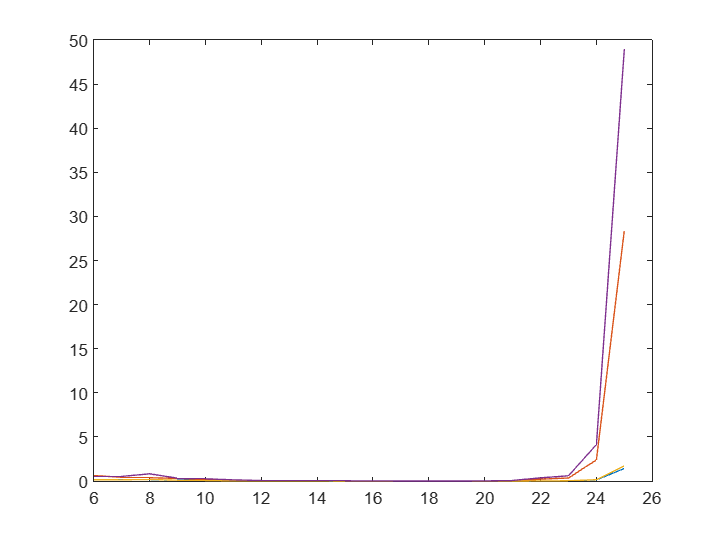

% b)

xd = 0;
xu = 10;
wb = zeros(1,19);
eb5b = zeros(4,19);

for len = 6 : 25
    %len = 2;
    
    
    
    xi = linspace (xd,xu,1000);
    yi = exp(sin(xi));
    
    
    x = zeros(1,len);
    for c = 1 : len
        x(c) = cos((2*c-1)*pi/(2*len));
    end
    
    x = (x+1)*(xu-xd)/2+xd;
    y = exp(sin(x));
    p = zeros(1,len);
    
    for i = 1 : len
        tmp1=x;
        tmp1(i) = [];
        tmp2=poly(tmp1);
        tmp1=x(i)-tmp1;
        tmp2=tmp2*y(i)/prod(tmp1);
        p=p+tmp2;
    end
    
    b = zeros(2,1000);
    yo=polyval(p,xi);
    
    
    for a = 1 : 1000
        b(1,a) = abs(yi(a)-yo(a));
        b(2,a) = b(1,a)/abs(yi(a));
    end

    eb5b(1,len-5) = mean(b(1,:));
    eb5b(2,len-5) = max(b(1,:));
    eb5b(3,len-5) = mean(b(2,:));
    eb5b(4,len-5) = max(b(2,:));

    wb(len-5) = len;

end


figure;
plot(wb,eb5b);

format shortG
disp([wb;eb5b]);

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25
      0.19908      0.15876      0.15379     0.098206     0.068931     0.020368     0.017454     0.015986     0.012157    0.0079923    0.0037971    0.0013572    0.0012146    0.0010744   0.00089973    0.0028104     0.013619     0.026952       0.1278       1.4199
      0.62457      0.42185      0.37611      0.29347      0.15701     0.080946     0.056677     0.049582     0.029573     0.023023    0.0091352     0.005053    0.0039217    0.0030681    0.0075366     0.038744      0.21019      0.34383       2.3978       28.433
      0.15097      0.13563      0.18209     0.091617     0.065054     0.017168      0.01598     0.017893     0.013341    0.0079795    0.0036627    0.0013261   0.00096839    0.0013132   0.00096464    0.0031695     0.01

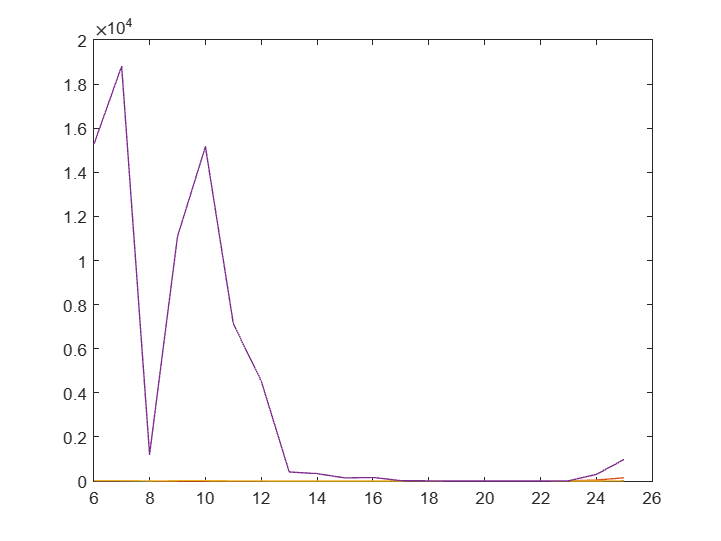

% c)

xd = 1.5;
xu = 21.5;
wb = zeros(1,19);
eb5c = zeros(4,19);

for len = 6 : 25    
    
    xi = linspace (xd,xu,1000);
    yi = log(xi).*sin(xi);
    
    
    x = zeros(1,len);
    for c = 1 : len
        x(c) = cos((2*c-1)*pi/(2*len));
    end
    
    x = (x+1)*(xu-xd)/2+xd;
    y = log(x).*sin(x);
    p = zeros(1,len);
    
    for i = 1 : len
        tmp1=x;
        tmp1(i) = [];
        tmp2=poly(tmp1);
        tmp1=x(i)-tmp1;
        tmp2=tmp2*y(i)/prod(tmp1);
        p=p+tmp2;
    end
    
    b = zeros(2,1000);
    yo=polyval(p,xi);
    
    
    for a = 1 : 1000
        b(1,a) = abs(yi(a)-yo(a));
        b(2,a) = b(1,a)/abs(yi(a));
    end

    eb5c(1,len-5) = mean(b(1,:));
    eb5c(2,len-5) = max(b(1,:));
    eb5c(3,len-5) = mean(b(2,:));
    eb5c(4,len-5) = max(b(2,:));

    wb(len-5) = len;

end


figure;
plot(wb,eb5c);


format shortG
disp([wb;eb5c]);

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25
       1.6474       1.6049       1.3323      0.90553      0.75065      0.27357      0.23513     0.052491     0.045869    0.0070477    0.0062018   0.00070928   0.00062284   0.00040008   0.00015124    0.0066899     0.011554      0.15643        3.203       10.466
       5.0519       4.5483       4.0071       2.3702       1.7779      0.71727      0.47983      0.14585      0.08714       0.0211     0.011258    0.0022619    0.0010957    0.0049952    0.0016808     0.075196      0.11609       3.0862        45.52       148.46
       18.348       21.752       3.4031       13.191       16.904       7.6745       5.1561      0.51804      0.42185      0.15222      0.18142     0.017647     0.010151   0.00042721   0.00095441    0.0061789     0.01

**Porównanie wyników z zadania 4 i 5**

**poniżej predstawiony jest błąd bezwzględny wyników dla róznej ilości węzłów interpolujących dla funkcji a)**

for i = 1 : length(eb4a);
    iwa(i) = i+5;
end
pkta=abs(eb4a-eb5a);
disp([iwa;pkta])

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25           26           27           28           29           30
   0.00051199   0.00019256   2.2574e-05   8.4547e-06   8.5717e-07   2.6087e-07   2.1307e-08   5.2984e-09   3.2444e-10    1.401e-10   3.1638e-10   5.4881e-12   1.0121e-08   9.9049e-09   2.6453e-07   2.4963e-09   9.9403e-07   4.1151e-05   0.00016982      3.6e-05   0.00038564    0.0048201     0.025695     0.063623      0.26939
    0.0076107    0.0028511    0.0004632   0.00013348   1.6342e-05   3.8891e-06   3.8156e-07   7.8154e-08   5.5763e-09   1.8983e-09   5.3554e-09   7.7212e-11   1.9461e-07   1.6374e-07   6.2736e-06   6.1202e-08   2.8824e-05    0.0011013     0.004865    0.0015214    0.0094238       0.1766       0.7727       2.3179       10.683
    0.0012345    0.001

**poniżej predstawiony jest błąd bezwzględny wyników dla róznej ilości węzłów interpolujących dla funkcji b)**

for i = 1 : length(eb4b);
    iwb(i) = i+5;
end
pktb=abs(eb4b-eb5b);
disp([iwb;pktb])

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25
     0.089951      0.11211     0.054312      0.06609     0.047385     0.018852     0.083378     0.063293     0.033639     0.027495     0.038778     0.018017     0.041081     0.028033     0.016126    0.0064701      0.15952       1.2197       11.075       44.154
      0.56668      0.52961      0.75372        1.171      0.55581      0.28861      0.79924       1.1194      0.79806      0.69214       0.7644      0.43841      0.69275      0.78373      0.28585      0.09044        2.798       18.542       144.42       966.08
     0.090915     0.064789     0.018725     0.060398     0.030445     0.011513     0.077662     0.069522     0.020346     0.035155      0.04554     0.022991     0.042571     0.036672     0.018336     0.005915      0.1

**poniżej predstawiony jest błąd bezwzględny wyników dla róznej ilości węzłów interpolujących dla funkcji c)**

for i = 1 : length(eb4c);
    iwc(i) = i+5;
end
pktc=abs(eb4c-eb5c);
disp([iwc;pktc])

            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20           21           22           23           24           25
      0.29728       1.3611      0.34473       1.3858      0.56408      0.72694      0.37336      0.24247      0.14019     0.056682     0.035036     0.010012    0.0070861    0.0010146    0.0072235     0.030018       2.8507       39.291        714.1       937.98
       1.9111       6.2101       4.2187       12.499        8.074       8.5464       5.3351       3.4129       2.0789      0.93364      0.55487      0.19142      0.11011     0.022396       0.1381      0.16312       32.846       442.98        10788        19762
       5.0419       120.03       119.81       79.779       56.122       13.361        6.668      0.19651       1.5787      0.49333      0.76914      0.11645        0.153     0.014246     0.019023     0.044911       2.